# Setup

N = 20;
d = 2;
% rng(103)
arrangement = randn(N,d+1);

width = 10;
box = Polyhedron('lb',-width*ones(1,d), 'ub',width*ones(1,d));
x1 = interior_point(box.H)

x1 =      5
     0
     0


## Find the regions of the hyperplane arrangment

[regs, tree, leaves] = get_regions(box, arrangement);

% Turn the H representations into Polyhedron objects that can be plotted
regsP = cell(1,length(regs));
for i = 1:length(regs)
    regsP{i} = Polyhedron('H',regs{i});
end
regsP = [regsP{:}];

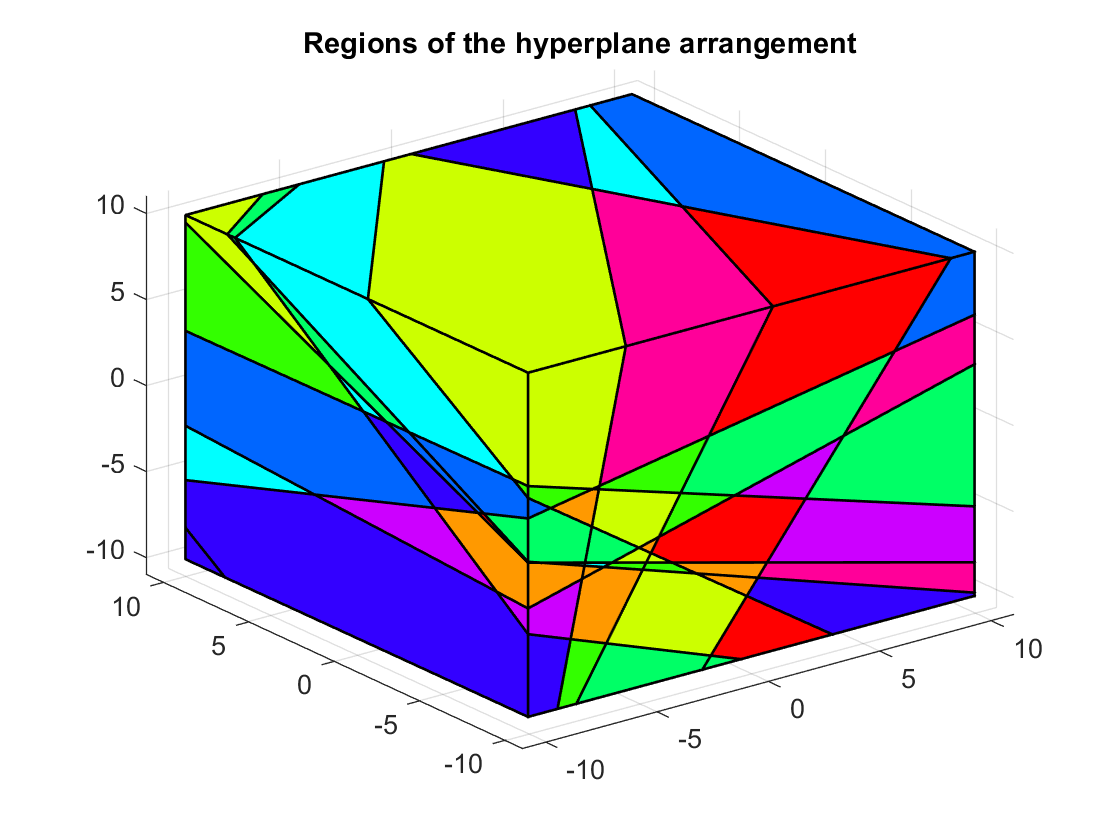

% Plot the regions
plot(regsP(logical(leaves)))
title("Regions of the hyperplane arrangement")


G = digraph();
G = addnode(G, num2str(1))

G =   digraph with properties:

    Edges: [0×1 table]
    Nodes: [1×1 table]


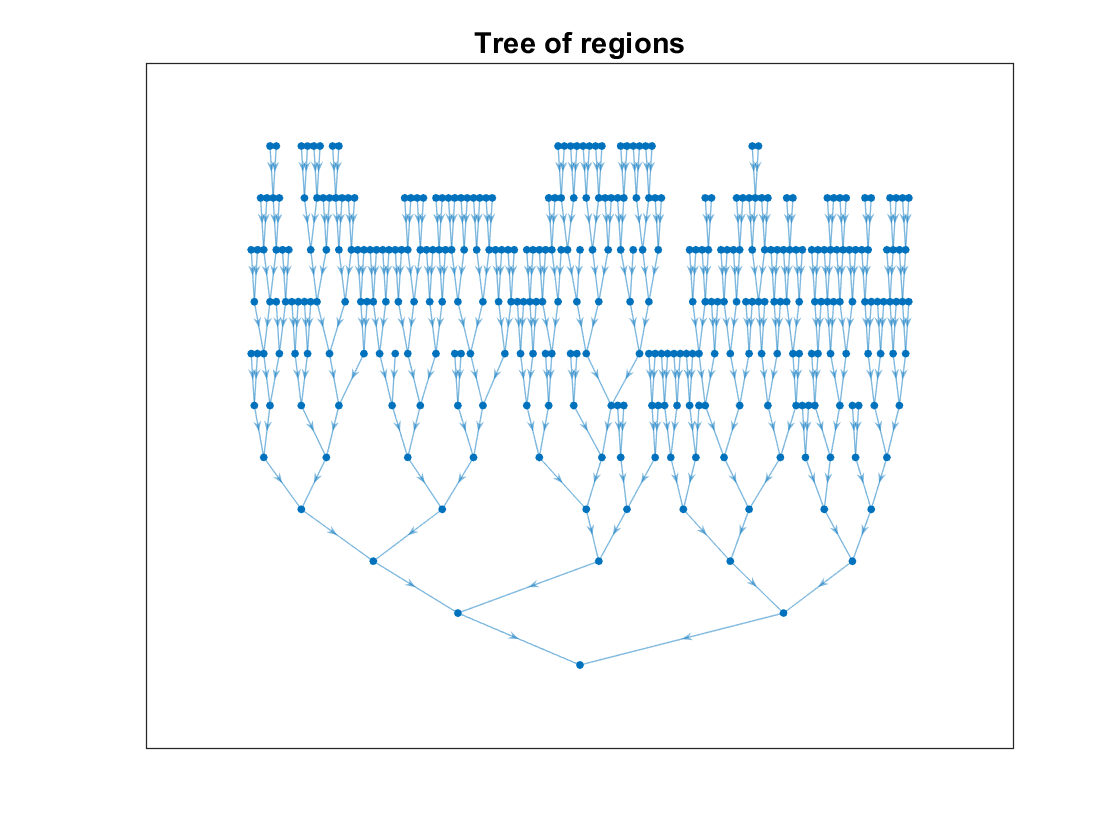

for i = 2:length(tree)
    G = addedge(G, num2str(i), num2str(tree(i)));
end
plot(G, 'layout', 'layered');
title("Tree of regions")

## Checking for intersections

There are two main methods: check all of the leaf nodes or check the parent regions first.

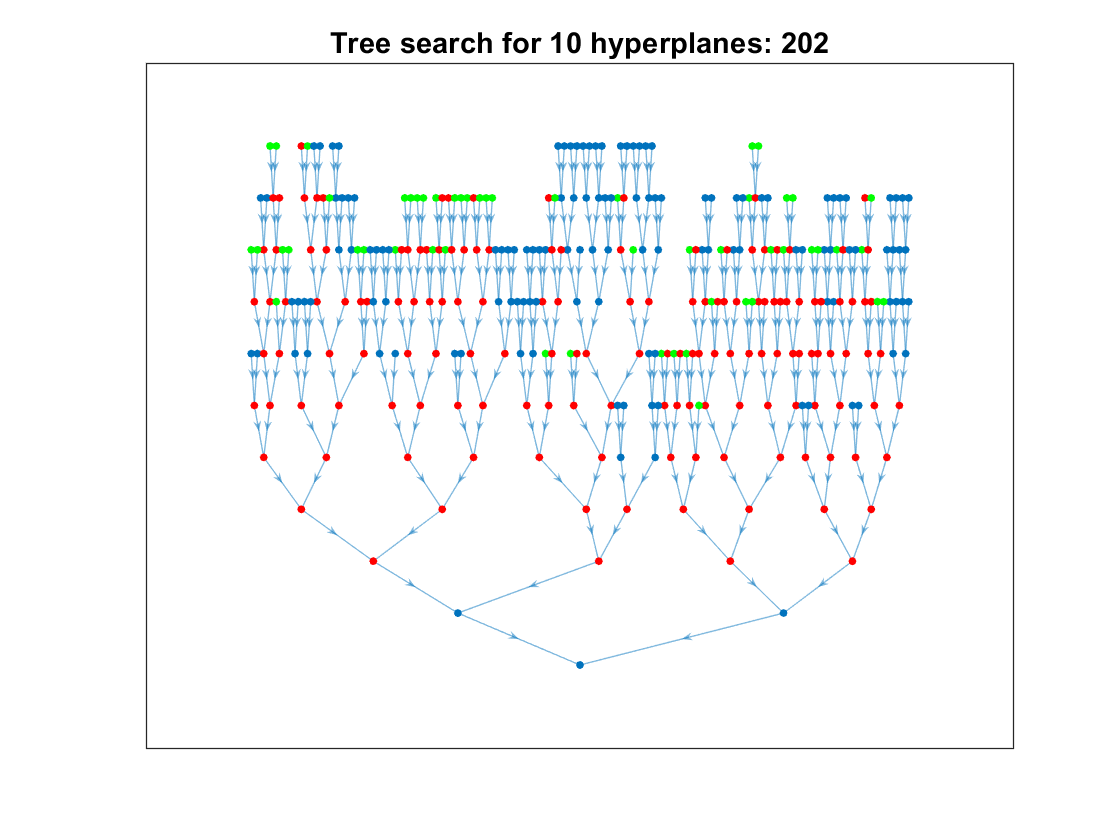

hplane = randn(1,d+1);

[checks, intersections] = check_intersections(hplane, regs, tree);
h = plot(G, 'layout', 'layered');
h.highlight(string(find(checks)), 'nodecolor', 'red')
h.highlight(string(find(intersections)), 'nodecolor', 'green')

title("Tree search for "+ N+" hyperplanes: "+sum(checks))

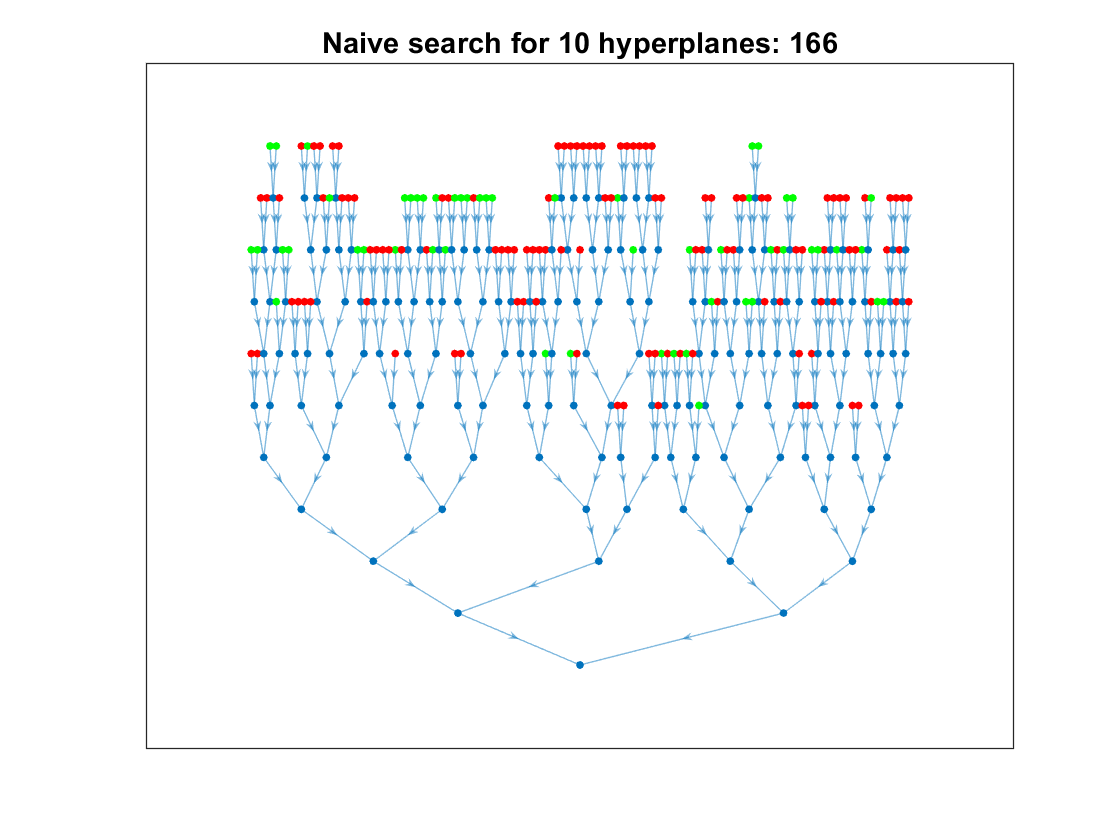


h = plot(G, 'layout', 'layered');
h.highlight(string(find(leaves)), 'nodecolor', 'red')
title("Naive search for "+ N+" hyperplanes: "+sum(leaves))
h.highlight(string(find(intersections)), 'nodecolor', 'green')

disp("Tree search for "+ N+" hyperplanes: "+sum(checks))

Tree search for 10 hyperplanes: 202


disp("Naive search for "+ N+" hyperplanes: "+sum(leaves))

Naive for 10 hyperplanes: 166


function [regs, tree, leaves] = get_regions(root, arrangement)
% Naive algorithm that returns an intersection tree
regs = {root.H};
leaves = true;
tree = 0;
for i = 1:size(arrangement,1)
   hplane = arrangement(i,:);
   for r = find(leaves)          
       p = Polyhedron('He',hplane);
       p = Polyhedron('He',hplane);
       P = Polyhedron('H',regs{r});
       if P.doesIntersect(p)
           regs{end+1} = [regs{r} ; hplane];
           regs{end+1} = [regs{r} ; -hplane];
           tree = [tree, r,r];
           leaves(r) = false;
       end
   end
   leaves = [leaves, true(1,length(regs) - length(leaves))];
end
% leaves = logical(leaves);
end

function [checks, intersections] = check_intersections(hplane, regs, tree)
    checks = false(size(regs));
    intersections = false(size(regs));
    hplane = Polyhedron('He', hplane);
    
    % Start the recursion from the root region
    rec(1)
    
    % Alternatively, you can skip the regions that are guaranteed to have
    % intersections
%     for r = find(tree==2 | tree==3)
%         rec(r)
%     end
    
    function rec(i)
        checks(i) = true;
        P = Polyhedron('H', regs{r});
        if hplane.doesIntersect(P)
            children = find(tree == i, 2);
            if isempty(children)
                intersections(i) = true;
                return
            end
            for r = children
                rec(r);
            end  
        end   
    end
end  

function x = interior_point(H)

    options = optimoptions('linprog','Algorithm','dual-simplex','Display','none','OptimalityTolerance',1.0000e-07); 
    [n,d] = size(H);
    K = 10000;
    f = [-1 ; zeros(d-2,1)];
    
    A = H(:,1:end-1);
    A(:,1) = A(:,1)+1;
    
    b = H(:,end);
    
    x = linprog(f, A, b,[],[],[],[K; inf(d-2,1)], options);

end